addpath("C:\Users\Liushoukang\Desktop\VMIE\src\")
P = imread("image/camera256.bmp");
P = double(P);       % 明文图像
C = imread("image/Lena256.bmp");
C = double(C);                 % 载体图像
[Hc, Nc] = size(C); 
[Hp, Np] = size(P);                          
% 与明文相关联
Message = hash(P, 'SHA-256');  % 输出为64位的十六进制数

m1 = hex2dec(Message(1:4))   + hex2dec(Message(5:8))   + hex2dec(Message(9:12))  + hex2dec(Message(13:16));
m2 = hex2dec(Message(17:20)) + hex2dec(Message(21:24)) + hex2dec(Message(25:28)) + hex2dec(Message(29:32));
m3 = hex2dec(Message(33:36)) + hex2dec(Message(37:40)) + hex2dec(Message(41:44)) + hex2dec(Message(45:48));
m4 = hex2dec(Message(49:52)) + hex2dec(Message(53:56)) + hex2dec(Message(57:60)) + hex2dec(Message(61:64));

c1 = RSA(m1, "encrypt");
c2 = RSA(m2, "encrypt");
c3 = RSA(m3, "encrypt");
c4 = RSA(m4, "encrypt");

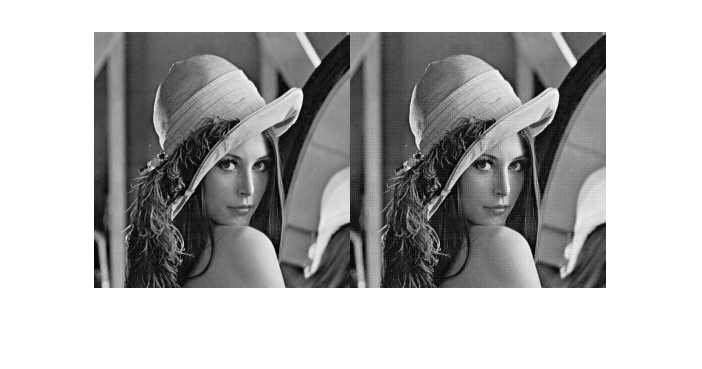

% 密钥流生成
x0 = cos((floor(c1./m1)-c1./m1)*pi);
y0 = cos((floor(c2./m2)-c2./m2)*pi);
z0 = cos((floor(c3./m3)-c3./m3)*pi);
T = mod(floor(c1./m1)+floor(c2./m2)+floor(c3./m3)+floor(c4./m4),1000);
[X,Y,Z]=NewCheyLCM(x0,y0,z0,T,Hp*Np);

% 按奇偶性分块稀疏化矩阵
[P01,P02,P03,P04] = Block(P);
V01 = Sparse(P01,1);
V02 = Sparse(P02,1);
V03 = Sparse(P03,1);
V04 = Sparse(P04,1);

% 分块测量矩阵
CR=0.25;                  % 压缩率
R=PartHadamardMtx(Hp/2,Np/2);
Rx1=X(1:Hp/2*CR);Rx2=X(1:Np/2);
[~,Rx1Index]=sort(Rx1);
[~,Rx2Index]=sort(Rx2);
R=R(Rx1Index,Rx2Index);  % 对所有采样块使用同一个测量矩阵

% DCT_block
Db=mat2cell(C,zeros(1,Hc/4)+4,zeros(1,Nc/4)+4);           % 意思是将其行列分别分成【4，4，4，'''】  ，【4，4，4，'''】
Db1=cell2mat(cellfun(@iwt,Db,'UniformOutput', false));    % 对每个块进行iwt变换

% 利用测量矩阵得到测量值矩阵
V11=R*V01;
V12=R*V02;
V13=R*V03;
V14=R*V04;

L=999;                                  % 量化范围值为0-999
V2=[V11,V12;V13,V14];                   % 测量值矩阵重组为矩阵V2
[V3,V2Max,V2Min]=Quantization(V2,L);    % 进行V2量化得到V3
V33=mod(V3,10);                         % 获取量化测量值矩阵的个位值
V32=mod(floor(V3./10),10);              %                   十位值
V31=mod(floor(V3./100),10);             %                   百位值

V4=Restruct([V31,V32,V33],Hc,1);
Db2=Db1+V4;
Db3=cell2mat(cellfun(@iiwt,mat2cell(Db2,zeros(1,Hc/4)+4,zeros(1,Nc/4)+4),'UniformOutput', false)); % IIWT变换
imshowpair(uint8(C),uint8(Db3),'montage')

psnr(uint8(Db3),uint8(C))

ans = 35.9788

ssim(uint8(Db3),uint8(C))

ans = 0.9183

entropy(uint8(Db3))

ans = 7.6006

entropy(uint8(C))

ans = 7.5683

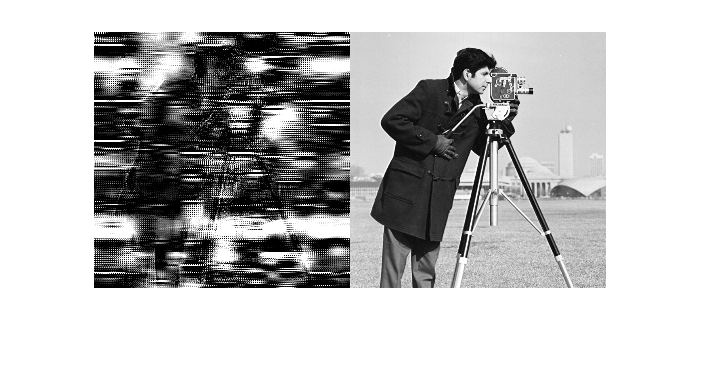

% 解密
IDb3=cell2mat(cellfun(@iwt,mat2cell(Db3,zeros(1,Hc/4)+4,zeros(1,Nc/4)+4),'UniformOutput',false));
IV4=Restruct(IDb3-Db1,Hc,0);
IV31=IV4(:,1:Hc);
IV32=IV4(:,(Hc+1):(2*Hc));
IV33=IV4(:,(2*Hc+1):3*Hc);
IV3=IV31*100+IV32*10+IV33;
IV2=IQuantization(IV3,V2Max,V2Min,L);
IV11=IV2(1:Hc/8,1:Nc/2);
IV12=IV2(1:Hc/8,(1+Nc/2):Nc);
IV13=IV2((1+Hc/8):Hc/4,1:Nc/2);
IV14=IV2((1+Hc/8):Hc/4,(1+Nc/2):Nc);

% OMP重建算法
% 恢复矩阵
IV01=zeros(Hp/2,Np/2);
IV02=zeros(Hp/2,Np/2);
IV03=zeros(Hp/2,Np/2);
IV04=zeros(Hp/2,Np/2);

% 按列循环
for i=1:Np/2 
    % 通过OMP，返回每一列信号对应的恢复值（小波域）
    rec1=omp(IV11(:,i),R,Hp/2);
    rec2=omp(IV12(:,i),R,Hp/2);
    rec3=omp(IV13(:,i),R,Hp/2);
    rec4=omp(IV14(:,i),R,Hp/2);
    % 恢复值矩阵，用于反变换
    IV01(:,i)=rec1;
    IV02(:,i)=rec2;
    IV03(:,i)=rec3;
    IV04(:,i)=rec4;
end
IP11=Sparse(IV01,0); 
IP12=Sparse(IV02,0);
IP13=Sparse(IV03,0);
IP14=Sparse(IV04,0);

IP01=uint8(IP11);
IP02=uint8(IP12);
IP03=uint8(IP13);
IP04=uint8(IP14);

IP=zeros(Hp,Np);
IP(1:2:Hp,1:2:Np)=IP01;
IP(1:2:Hp,2:2:Np)=IP02;
IP(2:2:Hp,1:2:Np)=IP03;
IP(2:2:Hp,2:2:Np)=IP04;

imshowpair(uint8(IP),uint8(P),'montage')

psnr(uint8(IP),uint8(P))

ans = 5.6537

ssim(uint8(IP),uint8(P))

ans = 0.0606

entropy(uint8(IP))

ans = 5.2858

entropy(uint8(P))

ans = 6.9046

function [X,Y]=Logistic(N)
    X=zeros(1,N);Y=zeros(1,N);
    nanda=0.65;
    n=200;
    x=0.35;y=0.25;
    for i=1:n+N
        x1=x+nanda*(x-x^2+y);
        y1=y+nanda*(y-y^2+x);
        x=x1;y=y1;
        if i>n
            X(i-n)=x;
            Y(i-n)=y;
        end
    end
end

function X=iwt(A)
    [aa,bb,cc,dd]=IWT(A);
    X=[aa,bb;cc,dd];
end
function X=iiwt(A)  
    [M,N]=size(A);
    X=IIWT(A(1:M/2,1:N/2),A(1:M/2,(N/2+1):N),A((M/2+1):M,1:N/2),A((M/2+1):M,(N/2+1):N));
end